# NB-IoT simulation

## ofdm parameters

clear
numSC=12;%number subcarriers, nbiot=12
numSym=28;%number ofdm symbols, nbiot=grouped 7 per frame but more for this sim
SCS=15e3;%subcarrier spacing, nbiot=15kHz


## simulation parameters

dataLength=numSC*numSym*2;
randomData=true;
nLoops=8;
filtersOn=false;
plotSpec=false;
maxSNR=22;
dopplerShift=20e3;

## transmission


%base message
if randomData
    messageBits= randi([0 1],dataLength,1)
else
    messageBits=ones(dataLength,1)
end

messageBits =      0
     0
     1
     1
     0
     0
     1
     0
     1
     1



%map bits to qpsk symbols
messageInts=bit2int(messageBits,2)% grouped by 2 bits, converted to dec

messageInts =      0
     3
     0
     2
     3
     3
     3
     3
     3
     0


symbolMap=[1+1i, -1+1i, 1-1i, -1-1i] / sqrt(2); %normalized QPSK constellation points
messageSymbols = zeros(size(messageInts, 1), 1);
for k = 1:size(messageInts, 1)
    idx = messageInts(k) + 1; %map index
    messageSymbols(k) = symbolMap(idx); %symbolmap
end
messageSymbols

messageSymbols =    0.7071 + 0.7071i
  -0.7071 - 0.7071i
   0.7071 + 0.7071i
   0.7071 - 0.7071i
  -0.7071 - 0.7071i
  -0.7071 - 0.7071i
  -0.7071 - 0.7071i
  -0.7071 - 0.7071i
  -0.7071 - 0.7071i
   0.7071 + 0.7071i


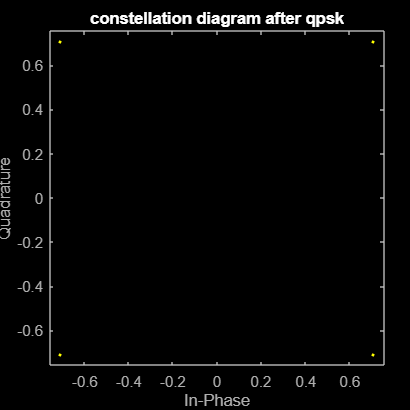

%plot scatterplot
figure;
scatterplot(messageSymbols);
title('constellation diagram after qpsk');

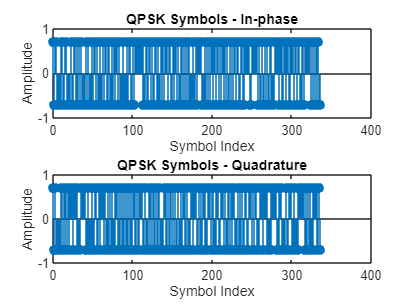


%plot time domain
figure;
subplot(2,1,1);
stem(real(messageSymbols), 'filled');
title('QPSK Symbols - In-phase');
xlabel('Symbol Index');
ylabel('Amplitude');
subplot(2,1,2);
stem(imag(messageSymbols), 'filled');
title('QPSK Symbols - Quadrature');
xlabel('Symbol Index');
ylabel('Amplitude');

% %ofdm
% % PARALLEL TO SERIAL STAP LOOPT FOUT
% numSC=12;% # subcarriers
% cpLen=3;%cyclic prefix length
% numSym=7;% # ofdm symbols
% bandwidth=180e3;
% SCS=15e3;
% carrierFreq=890e6;
% 
% numSymbolsRequired = numSC * numSym;
% if length(messageSymbols) < numSymbolsRequired
%     error('Not enough symbols to fill the OFDM frame');
% end
% 
% ofdmSymbolsMatrix = reshape(messageSymbols(1:numSymbolsRequired), numSC, numSym);%reshape into 12 carrier x7 symbols frame in freq domain
% 
% timeDomainSymbols = ifft(ofdmSymbolsMatrix, numSC);%time domain frame, 12 samples
% 
% cpSymbols = [timeDomainSymbols(end-cpLen+1:end, :); timeDomainSymbols];
% 
% txSignalOFDMA = cpSymbols(:);% (:) reshapes matrix into column
% 
% 
% 
% figure
% scatterplot(txSignalOFDMA)
% title('constellation diagram after OFDM');
% 
% % Plot the time domain signal
% figure;
% subplot(2,1,1);
% plot(real(txSignalOFDMA));
% title('OFDM Signal Time Domain');
% xlabel('Sample Index');
% ylabel('Amplitude');
% 
% [pxx,f] = pspectrum(txSignalOFDMA);
% subplot(2,1,2);
% plot(f,pow2db(pxx))
% grid on
% title('OFDM Signal Freq Domain');
% xlabel('Frequency (Hz)')
% ylabel('Power Spectrum (dB)')


% numSC=12;% # subcarriers
% numSym=21;% # ofdm symbols
% SCS=15e3;
BW=SCS*numSC;
samplingRate = numSC * SCS;
symbolDuration = 1 / SCS; % Duration of one OFDM symbol (T=1/FS = 1/SCS)
SPS = round(samplingRate * symbolDuration);
t = (0:SPS-1) / samplingRate; %time vector
ofdmSignal = zeros(1, numSym * SPS);
cpLen=round(SPS/4);%cyclic prefix length


ofdmMatrix = zeros(numSC,numSym);%12x7 in nbiot
for symbolIdx =1:numSym
    ofdmMatrix(:,symbolIdx)=messageSymbols((symbolIdx-1)*numSC+1:numSC*symbolIdx);
end
ofdmMatrix%every column represents 12 carriers for 1 ofdm symbol

ofdmMatrix =    0.7071 + 0.7071i  -0.7071 - 0.7071i  -0.7071 - 0.7071i  -0.7071 + 0.7071i   0.7071 - 0.7071i  -0.7071 + 0.7071i  -0.7071 - 0.7071i  -0.7071 - 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i   0.7071 + 0.7071i   0.7071 - 0.7071i  -0.7071 + 0.7071i   0.7071 + 0.7071i  -0.7071 + 0.7071i  -0.7071 - 0.7071i  -0.7071 - 0.7071i  -0.7071 + 0.7071i   0.7071 + 0.7071i   0.7071 - 0.7071i  -0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 + 0.7071i  -0.7071 + 0.7071i  -0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 + 0.7071i  -0.7071 - 0.7071i
  -0.7071 - 0.7071i  -0.7071 + 0.7071i  -0.7071 + 0.7071i  -0.7071 + 0.7071i  -0.7071 + 0.7071i  -0.7071 + 0.7071i   0.7071 + 0.7071i  -0.7071 + 0.7071i  -0.7071 + 0.7071i   0.7071 + 0.7071i   0.7071 - 0.7071i  -0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 - 0.7071i  -0.7071 - 0.7071i  -0.7071 - 0.7071i   0.7071 + 0.7071i   0.7071 + 0.7071i  -0.7071 + 0.7071i  -0.7071 + 0.707

%the entire column/symbol is transmitted at once at different freq

timeDomainSymbolMatrix = ifft(ofdmMatrix, numSC);%time domain frame, 12 samples per symbol
%every colum contains the sample of the symbol over time, the column
%elements are transmitted one by one
cp=timeDomainSymbolMatrix(end-(cpLen-1):end,:)

cp =    0.0000 + 0.1179i  -0.1179 - 0.1179i  -0.1179 + 0.2357i   0.1179 + 0.2357i   0.3536 + 0.2357i  -0.2357 + 0.0000i   0.0000 + 0.2357i   0.2357 + 0.0000i   0.2357 + 0.2357i  -0.1179 - 0.2357i   0.2357 - 0.3536i   0.0000 + 0.0000i  -0.2357 + 0.0000i   0.2357 + 0.2357i   0.1179 + 0.0000i  -0.2357 + 0.0000i  -0.2357 + 0.2357i  -0.3536 + 0.0000i  -0.1179 + 0.0000i   0.4714 + 0.1179i  -0.2357 - 0.1179i   0.0000 + 0.0000i   0.1179 - 0.1179i  -0.1179 + 0.2357i  -0.1179 + 0.4714i   0.2357 - 0.2357i  -0.1179 + 0.0000i   0.2357 - 0.3536i
  -0.1179 + 0.0000i  -0.2946 + 0.1021i  -0.1610 - 0.1610i   0.2630 - 0.2199i  -0.2630 + 0.2199i   0.1021 + 0.0589i   0.2199 + 0.1768i  -0.2199 + 0.2630i  -0.0431 + 0.1610i   0.2473 - 0.1610i  -0.2199 - 0.1452i   0.2041 + 0.2041i  -0.3378 - 0.2630i   0.3378 + 0.0589i  -0.2630 + 0.1336i  -0.1610 - 0.0747i   0.0431 - 0.0747i   0.0705 - 0.1768i  -0.1452 - 0.1021i  -0.2788 + 0.0431i   0.3062 + 0.2630i   0.2630 - 0.4556i  -0.1768 + 0.1021i  -0.0158 - 0.0905i  -0.3

timeDomainSymbolMatrix=[cp; timeDomainSymbolMatrix]%add cp

timeDomainSymbolMatrix =    0.0000 + 0.1179i  -0.1179 - 0.1179i  -0.1179 + 0.2357i   0.1179 + 0.2357i   0.3536 + 0.2357i  -0.2357 + 0.0000i   0.0000 + 0.2357i   0.2357 + 0.0000i   0.2357 + 0.2357i  -0.1179 - 0.2357i   0.2357 - 0.3536i   0.0000 + 0.0000i  -0.2357 + 0.0000i   0.2357 + 0.2357i   0.1179 + 0.0000i  -0.2357 + 0.0000i  -0.2357 + 0.2357i  -0.3536 + 0.0000i  -0.1179 + 0.0000i   0.4714 + 0.1179i  -0.2357 - 0.1179i   0.0000 + 0.0000i   0.1179 - 0.1179i  -0.1179 + 0.2357i  -0.1179 + 0.4714i   0.2357 - 0.2357i  -0.1179 + 0.0000i   0.2357 - 0.3536i
  -0.1179 + 0.0000i  -0.2946 + 0.1021i  -0.1610 - 0.1610i   0.2630 - 0.2199i  -0.2630 + 0.2199i   0.1021 + 0.0589i   0.2199 + 0.1768i  -0.2199 + 0.2630i  -0.0431 + 0.1610i   0.2473 - 0.1610i  -0.2199 - 0.1452i   0.2041 + 0.2041i  -0.3378 - 0.2630i   0.3378 + 0.0589i  -0.2630 + 0.1336i  -0.1610 - 0.0747i   0.0431 - 0.0747i   0.0705 - 0.1768i  -0.1452 - 0.1021i  -0.2788 + 0.0431i   0.3062 + 0.2630i   0.2630 - 0.4556i  -0.1768 + 0.1021i  -0.


timeDomainSymbols=reshape (timeDomainSymbolMatrix,[],1)

timeDomainSymbols =    0.0000 + 0.1179i
  -0.1179 + 0.0000i
   0.2041 + 0.2357i
  -0.1179 - 0.2357i
   0.3536 + 0.3220i
  -0.1179 + 0.0000i
   0.0000 - 0.1179i
   0.4398 - 0.0863i
   0.3536 - 0.0863i
  -0.1179 + 0.0000i


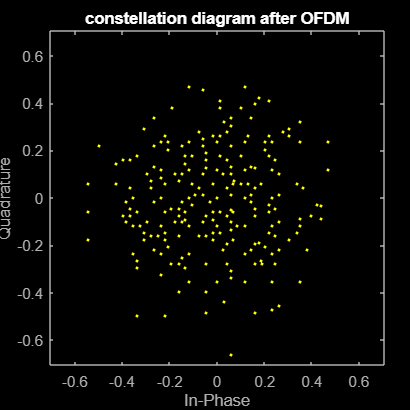

% plot ofdm signal

if plotSpec 
figure
window=hamming(7);
spectrogram(timeDomainSymbols,window,round(length(window)/2),BW)
end

figure
scatterplot(timeDomainSymbols)
title('constellation diagram after OFDM');

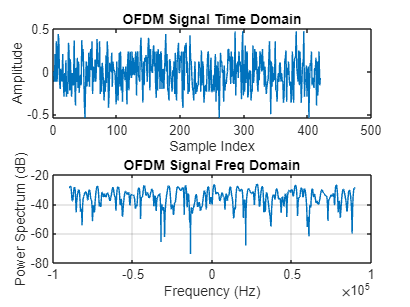


% Plot the time domain signal
figure;
subplot(2,1,1);
plot(real(timeDomainSymbols));
title('OFDM Signal Time Domain');
xlabel('Sample Index');
ylabel('Amplitude');

[pxx,f] = pspectrum(timeDomainSymbols,samplingRate);
subplot(2,1,2);
plot(f,pow2db(pxx))
grid on
title('OFDM Signal Freq Domain');
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')

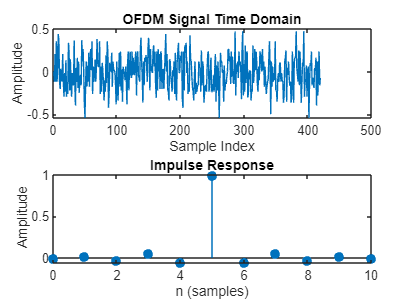

%upsampling
L = 1;  % Upsampling factor
rolloff = 0.25;  % Roll-off factor for the RRC filter
span = 10;  % Filter span in symbols

txSignalUpsampled = upsample(timeDomainSymbols, L);

rrcFilter = rcosdesign(rolloff, span, L);
impz(rrcFilter)

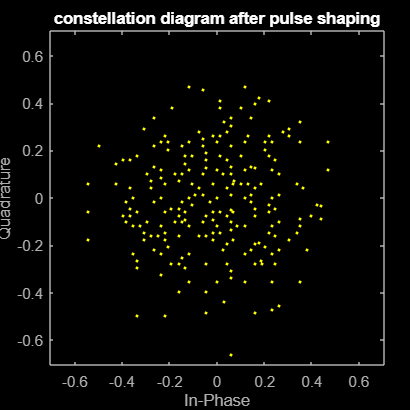

if filtersOn
    txSignalShaped = conv(txSignalUpsampled, rrcFilter, 'same');
else
    txSignalShaped = txSignalUpsampled;

end

figure
scatterplot(txSignalShaped)
title('constellation diagram after pulse shaping');

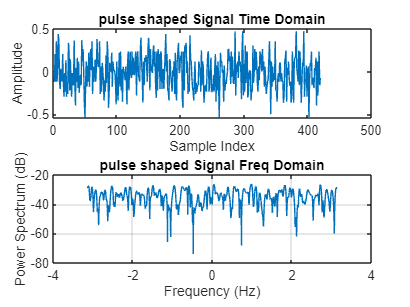


% Plot the time domain signal
figure;
subplot(2,1,1);
plot(real(txSignalShaped));
title('pulse shaped Signal Time Domain');
xlabel('Sample Index');
ylabel('Amplitude');

[pxx,f] = pspectrum(txSignalShaped);
subplot(2,1,2);
plot(f,pow2db(pxx))
grid on
title('pulse shaped Signal Freq Domain');
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')

% %convert to 900 MHz
% Fc=900e6;
% Fs=2*180e3;
% t = (0:length(txSignalShaped)-1)' / Fs; % Time vector
% cosCarrier = cos(2 * pi * Fc * t);
% sinCarrier = sin(2 * pi * Fc * t);
% txPassband = real(txSignalShaped) .* cosCarrier - imag(txSignalShaped) .* sinCarrier;
% % Plot the time domain signal after upconversion
% figure;
% plot(t(1:length(txPassband)), txPassband); % Plot a segment for better visualization
% title('Passband Signal - Time Domain');
% xlabel('Time (s)');
% ylabel('Amplitude');
% %freq
% [pxx,f] = pspectrum(txSignalShaped,Fs);
% subplot(2,1,2);
% plot(f+Fc,pow2db(pxx))
% grid on
% title('pulse shaped Signal Freq Domain');
% xlabel('Frequency (Hz)')
% ylabel('Power Spectrum (dB)')

## channel

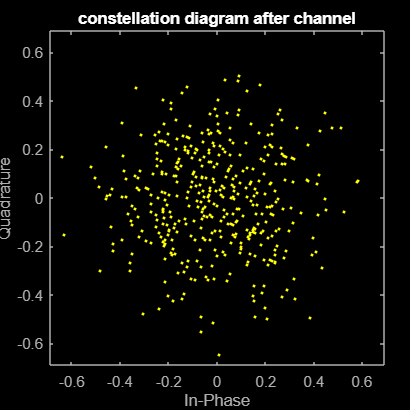

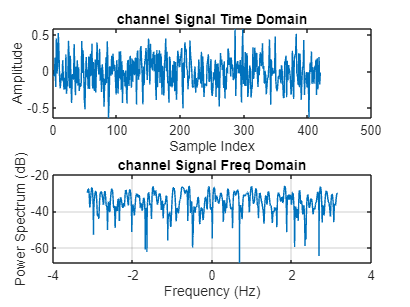

for counter=1:nLoops
%check filters, error rate is te hoog?

SNR=20-(nLoops-counter);
% rxSignal=awgn(txSignalShaped,SNR);

rxSignal=awgn(txSignalUpsampled,SNR);
% rxSignal=txSignalShaped;

if counter==nLoops %only plot in last loop
    % Plot the time domain signal after channel
    figure
    scatterplot(rxSignal)
    title('constellation diagram after channel');
    
    % Plot the time domain signal
    figure;
    subplot(2,1,1);
    plot(real(rxSignal));
    title('channel Signal Time Domain');
    xlabel('Sample Index');
    ylabel('Amplitude');
    
    [pxx,f] = pspectrum(rxSignal);
    subplot(2,1,2);
    plot(f,pow2db(pxx))
    grid on
    title('channel Signal Freq Domain');
    xlabel('Frequency (Hz)')
    ylabel('Power Spectrum (dB)')
end

## receiver

% %downconvert to baseband
% I_component = rxSignal .* cosCarrier;
% Q_component = rxSignal .* sinCarrier;
% 
% filterOrder = 64;
% cutoffFreq = Fc / (2 * Fs); % Normalized cutoff frequency
% lpFilt = designfilt('lowpassfir', 'FilterOrder', filterOrder, 'CutoffFrequency', 0.5);
% 
% I_baseband = filtfilt(lpFilt, I_component);
% Q_baseband = filtfilt(lpFilt, Q_component);
% 
% rxBaseband = I_baseband - 1i * Q_baseband;

%matched filter
if filtersOn
    matchedFilter = rcosdesign(rolloff, span, L);
    rxSignalFiltered = conv(rxSignal, matchedFilter, 'same');
else
    rxSignalFiltered = rxSignal;

end

rxSignalFiltered

rxSignalFiltered =    0.0279 + 0.0352i
  -0.1369 + 0.2111i
   0.2392 + 0.2607i
   0.0498 - 0.0316i
   0.1539 + 0.6560i
  -0.2953 - 0.0632i
   0.1253 - 0.2764i
   0.2805 - 0.0809i
   0.5240 - 0.1176i
   0.0544 + 0.0325i


rxSignalFiltered =    0.0679 + 0.2541i
  -0.3634 - 0.1336i
   0.2334 + 0.4017i
   0.0457 - 0.0230i
   0.3327 + 0.2954i
   0.2022 - 0.1454i
   0.2085 - 0.2771i
   0.6558 + 0.0733i
   0.3279 + 0.0917i
  -0.0120 - 0.1321i


rxSignalFiltered =    0.2856 - 0.0477i
  -0.0686 + 0.0896i
   0.3341 + 0.2907i
  -0.3610 - 0.1660i
   0.3811 + 0.2174i
  -0.1766 + 0.0383i
   0.1740 - 0.0267i
   0.4284 + 0.0853i
   0.2272 - 0.2792i
   0.0539 - 0.0747i


rxSignalFiltered =   -0.1342 + 0.0827i
  -0.1647 - 0.1307i
   0.1697 + 0.4457i
  -0.2494 - 0.1219i
   0.3080 + 0.1789i
  -0.1168 + 0.1245i
   0.0335 - 0.0603i
   0.4164 - 0.0677i
   0.3382 - 0.0542i
  -0.2292 + 0.0337i


rxSignalFiltered =   -0.0480 + 0.0353i
  -0.0018 + 0.0441i
   0.0988 + 0.1592i
   0.1147 - 0.1692i
   0.3938 + 0.3348i
  -0.0959 - 0.0738i
  -0.1515 - 0.1262i
   0.3342 - 0.0447i
   0.3691 - 0.0979i
   0.0349 - 0.0203i


rxSignalFiltered =    0.1069 - 0.0015i
  -0.0564 - 0.0983i
   0.3937 + 0.2489i
  -0.0521 - 0.2255i
   0.3855 + 0.3500i
  -0.1933 - 0.0749i
  -0.0174 - 0.0679i
   0.5109 - 0.1605i
   0.3803 - 0.1238i
  -0.0916 - 0.0636i


rxSignalFiltered =   -0.0838 + 0.1120i
  -0.1245 + 0.0380i
   0.1102 + 0.3334i
  -0.2419 - 0.2548i
   0.2328 + 0.3593i
  -0.2240 - 0.0208i
   0.0794 - 0.0372i
   0.4427 - 0.0995i
   0.4830 - 0.1530i
  -0.0549 - 0.0477i


rxSignalFiltered =   -0.0703 + 0.1573i
  -0.0298 - 0.0115i
   0.1848 + 0.1631i
  -0.2145 - 0.3459i
   0.4479 + 0.3504i
  -0.0299 + 0.0140i
   0.0681 - 0.0628i
   0.5239 - 0.0564i
   0.3060 - 0.0381i
  -0.0540 + 0.0040i


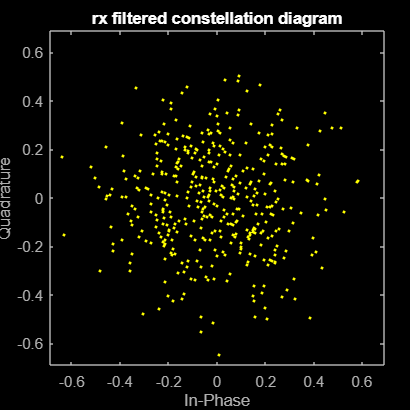


%downsample
% rxSignalDownsampled = downsample(rxSignalFiltered, L);
if counter==nLoops
    figure;
    scatterplot(rxSignalFiltered);
    title('rx filtered constellation diagram');
end


%cp
% rxSymbolsWithCP = reshape(rxSignalFiltered, [], numSym);
rxSymbolsWithCP = reshape(rxSignal, [], numSym);
rxSymbolsWithCP

rxSymbolsWithCP =    0.0279 + 0.0352i  -0.3223 - 0.0098i  -0.0526 - 0.0452i   0.1474 + 0.3137i   0.2418 + 0.4054i  -0.1926 - 0.3823i   0.1671 + 0.0665i   0.1245 - 0.0123i   0.2273 + 0.2533i   0.0083 - 0.4660i   0.2418 - 0.1118i  -0.3131 - 0.1402i  -0.2756 + 0.0860i   0.2418 + 0.0476i   0.0332 - 0.1424i  -0.2514 - 0.0860i  -0.2109 + 0.3224i  -0.2519 - 0.0821i  -0.1652 - 0.1360i   0.2492 + 0.2467i  -0.2468 + 0.0302i   0.2180 - 0.0455i   0.1083 + 0.0094i   0.0624 + 0.1993i   0.0442 + 0.4935i   0.1746 - 0.3608i  -0.0704 + 0.0021i   0.1070 - 0.5770i
  -0.1369 + 0.2111i  -0.3327 + 0.3664i  -0.1053 - 0.2048i  -0.0349 - 0.0940i  -0.4718 + 0.2246i  -0.0626 + 0.1074i   0.0968 + 0.4339i  -0.3197 + 0.2096i  -0.3840 + 0.2549i   0.3161 + 0.0471i  -0.1900 - 0.0799i   0.3517 + 0.3830i  -0.2974 - 0.1071i   0.4075 + 0.1815i  -0.3727 + 0.5150i  -0.1851 - 0.2964i   0.2137 + 0.0356i  -0.0083 - 0.1918i  -0.1824 - 0.0809i   0.0486 - 0.0788i   0.1440 + 0.3091i   0.6231 - 0.6559i  -0.3137 + 0.2002i  -0.1711 + 

rxSymbolsWithCP =    0.0679 + 0.2541i  -0.0914 - 0.0891i  -0.1145 + 0.3889i   0.2919 + 0.4726i   0.3122 + 0.0973i  -0.2116 + 0.0813i  -0.1377 + 0.2501i   0.2784 + 0.2015i   0.3439 + 0.0426i   0.1243 - 0.1595i   0.0909 - 0.2767i  -0.1543 + 0.0351i   0.0972 - 0.0564i   0.4161 + 0.2829i   0.0865 + 0.0482i  -0.3731 + 0.0608i  -0.1427 + 0.0586i  -0.1964 + 0.0668i  -0.0469 - 0.0692i   0.5272 + 0.1872i  -0.4403 - 0.0176i  -0.0027 + 0.1480i   0.2892 + 0.1002i  -0.1249 + 0.3198i  -0.2012 + 0.4008i   0.0993 - 0.4418i  -0.3735 - 0.0529i   0.0549 - 0.1869i
  -0.3634 - 0.1336i  -0.5024 - 0.1615i  -0.1179 - 0.2795i   0.2780 - 0.1818i  -0.4598 + 0.4821i   0.0022 - 0.0268i   0.1198 + 0.2490i  -0.1085 + 0.2768i  -0.0016 + 0.1943i   0.2473 - 0.0755i  -0.2483 - 0.1692i   0.2736 + 0.1835i  -0.4122 - 0.1475i   0.2794 + 0.0179i  -0.2474 + 0.3596i  -0.1186 - 0.0460i   0.2359 - 0.0802i   0.0318 - 0.1773i  -0.1183 - 0.0680i  -0.4896 - 0.0283i   0.0797 + 0.4174i   0.1959 - 0.4790i  -0.1686 + 0.2232i  -0.1413 - 

rxSymbolsWithCP =    0.2856 - 0.0477i  -0.2662 - 0.0890i  -0.2615 + 0.1818i   0.0966 + 0.2810i   0.6697 + 0.1739i  -0.3147 - 0.0264i  -0.0608 + 0.0449i   0.2866 - 0.0482i   0.3085 + 0.4317i  -0.0095 - 0.3191i   0.3214 - 0.4667i   0.3034 + 0.0745i  -0.2181 - 0.0252i   0.2916 + 0.3494i   0.1991 - 0.2001i  -0.0998 + 0.0429i  -0.2804 + 0.2915i  -0.4085 - 0.1258i  -0.0563 - 0.0993i   0.4519 + 0.2153i  -0.2738 - 0.2392i  -0.1127 + 0.2152i   0.1905 - 0.0975i  -0.0857 + 0.3942i  -0.1768 + 0.6289i   0.1668 - 0.1486i  -0.3451 - 0.1464i   0.2336 - 0.2931i
  -0.0686 + 0.0896i  -0.0609 - 0.0800i  -0.0984 - 0.2930i   0.2453 - 0.2838i  -0.1535 + 0.3034i   0.3046 + 0.1105i   0.2188 + 0.1913i  -0.2995 + 0.2224i  -0.0836 + 0.0021i   0.1750 - 0.1942i  -0.3573 - 0.0431i   0.3320 + 0.2988i  -0.3118 - 0.2234i   0.4660 + 0.2042i  -0.1543 + 0.1611i  -0.2357 - 0.1834i  -0.1918 - 0.0418i   0.0226 - 0.1420i   0.0568 - 0.0089i  -0.1718 + 0.3217i   0.2239 + 0.3102i   0.3709 - 0.5460i  -0.0527 + 0.2553i  -0.0118 - 

rxSymbolsWithCP =   -0.1342 + 0.0827i  -0.1223 - 0.0658i  -0.1002 + 0.3380i   0.2895 + 0.1023i   0.3029 + 0.0977i  -0.3567 - 0.1524i   0.0910 + 0.2455i   0.2939 - 0.0405i   0.2581 + 0.3778i  -0.1516 - 0.1319i   0.2506 - 0.4120i  -0.1946 + 0.0966i  -0.2044 + 0.0161i   0.2258 + 0.2362i   0.0988 - 0.0703i  -0.3616 - 0.0245i  -0.2069 + 0.1605i  -0.4789 + 0.1944i  -0.0596 + 0.1043i   0.5259 + 0.1828i  -0.2095 - 0.2473i  -0.0177 + 0.1869i   0.0252 + 0.0514i  -0.2319 + 0.3936i   0.0188 + 0.3642i   0.3104 - 0.1397i  -0.0912 - 0.1258i   0.4043 - 0.4008i
  -0.1647 - 0.1307i  -0.4359 + 0.1804i  -0.2661 - 0.0783i   0.1178 - 0.2579i  -0.2894 + 0.4677i   0.0535 + 0.1785i   0.3275 + 0.1454i  -0.3586 + 0.2794i  -0.0683 + 0.1175i   0.0572 - 0.0841i  -0.3541 - 0.1099i   0.2747 + 0.2500i  -0.4016 - 0.2660i   0.2624 + 0.1275i  -0.3418 + 0.2276i  -0.0444 - 0.1645i   0.0062 - 0.2315i   0.0648 - 0.0307i  -0.2240 - 0.0061i  -0.1516 - 0.1833i   0.2165 + 0.1630i   0.1313 - 0.5608i  -0.3824 + 0.0405i  -0.1561 - 

rxSymbolsWithCP =   -0.0480 + 0.0353i  -0.0869 - 0.1395i  -0.0036 + 0.0945i   0.3153 + 0.1508i   0.2154 + 0.3889i  -0.1875 - 0.1820i   0.1252 + 0.3073i   0.1902 - 0.0701i   0.1629 + 0.1176i  -0.1438 - 0.2693i   0.2194 - 0.3076i   0.0560 - 0.0034i  -0.1412 + 0.0341i   0.1650 + 0.1882i   0.0959 - 0.0451i  -0.2866 + 0.1567i  -0.2260 + 0.2403i  -0.3177 + 0.1204i  -0.2380 + 0.0308i   0.6296 + 0.0087i  -0.1688 - 0.3205i   0.1113 - 0.0182i   0.1301 - 0.1937i  -0.1759 + 0.2932i  -0.2243 + 0.5720i   0.1989 - 0.0270i  -0.2413 + 0.1959i   0.2463 - 0.4284i
  -0.0018 + 0.0441i  -0.1939 + 0.2542i  -0.3459 - 0.1413i   0.2140 - 0.2611i  -0.3013 + 0.2136i   0.1838 + 0.0371i   0.1937 + 0.0687i  -0.3247 + 0.3629i  -0.3001 + 0.1447i   0.1374 - 0.1290i  -0.1938 - 0.0950i   0.4688 + 0.1288i  -0.4274 - 0.2818i   0.4353 + 0.0957i  -0.3863 + 0.0815i   0.0373 - 0.1305i   0.1280 - 0.0983i  -0.1335 + 0.0100i  -0.2642 - 0.2869i  -0.2493 + 0.0403i   0.4297 + 0.4110i   0.4813 - 0.4600i  -0.1062 + 0.0607i   0.1343 - 

rxSymbolsWithCP =    0.1069 - 0.0015i  -0.1182 - 0.0617i  -0.2218 + 0.1377i   0.3043 + 0.3000i   0.3332 + 0.1903i  -0.1442 + 0.0436i  -0.0008 + 0.1307i   0.2652 + 0.0014i   0.2138 + 0.4011i  -0.2145 - 0.2097i   0.3125 - 0.3107i   0.0630 - 0.0464i  -0.1262 + 0.0603i   0.2796 + 0.0866i   0.1285 + 0.0462i  -0.3179 - 0.0477i  -0.1836 + 0.2280i  -0.2988 + 0.1698i  -0.1890 - 0.0771i   0.4238 - 0.0320i  -0.2763 + 0.0503i  -0.0085 + 0.0308i   0.1688 - 0.2287i  -0.1074 + 0.1426i  -0.0137 + 0.3376i   0.0690 - 0.1922i  -0.0828 - 0.0509i   0.2420 - 0.3144i
  -0.0564 - 0.0983i  -0.4277 + 0.0626i  -0.1815 - 0.1250i   0.1501 - 0.1814i  -0.2082 + 0.1109i   0.0531 + 0.0558i   0.3445 + 0.2020i  -0.2385 + 0.3950i  -0.2316 + 0.1444i   0.2216 - 0.1363i  -0.0420 - 0.0914i   0.1129 + 0.2692i  -0.2698 - 0.2806i   0.2485 + 0.1093i  -0.2002 + 0.0577i  -0.3266 - 0.1265i  -0.0691 - 0.1404i   0.1808 - 0.1635i  -0.1770 - 0.0884i  -0.3474 - 0.1213i   0.4383 + 0.2005i   0.1226 - 0.5536i  -0.2927 + 0.2265i   0.0705 + 

rxSymbolsWithCP =   -0.0838 + 0.1120i  -0.2061 - 0.1383i  -0.1185 + 0.1298i   0.0644 + 0.2855i   0.4369 + 0.1757i  -0.3460 - 0.0862i   0.0222 + 0.1972i   0.0824 - 0.0116i   0.1601 + 0.3504i  -0.2030 - 0.2301i   0.2971 - 0.2960i  -0.0522 + 0.0479i  -0.1697 + 0.0646i   0.2500 + 0.2072i   0.1249 - 0.0411i  -0.1784 + 0.0493i  -0.1815 + 0.2105i  -0.3351 - 0.1236i  -0.0927 + 0.0012i   0.3453 + 0.1520i  -0.2805 - 0.2106i  -0.0479 + 0.0013i   0.0987 - 0.0889i  -0.1590 + 0.1797i  -0.0673 + 0.4987i   0.2840 - 0.4152i  -0.1614 + 0.0036i   0.2575 - 0.2665i
  -0.1245 + 0.0380i  -0.2319 - 0.0424i  -0.2819 - 0.0473i   0.2341 - 0.2760i  -0.3526 + 0.1201i   0.0210 + 0.2099i   0.0881 + 0.2434i  -0.2149 + 0.2067i  -0.0662 + 0.2739i   0.2194 - 0.1954i  -0.2982 - 0.0723i   0.2768 + 0.1375i  -0.4065 - 0.2185i   0.3355 - 0.0217i  -0.1410 + 0.0964i  -0.0788 - 0.0282i  -0.0389 - 0.0848i   0.1394 - 0.1145i  -0.2271 + 0.0048i  -0.2271 + 0.0324i   0.3420 + 0.1303i   0.2899 - 0.5300i  -0.2502 + 0.1980i  -0.0099 - 

rxSymbolsWithCP =   -0.0703 + 0.1573i  -0.0813 - 0.0117i  -0.1134 + 0.2495i  -0.0244 + 0.2714i   0.3759 + 0.2211i  -0.2834 + 0.0402i  -0.0595 + 0.1328i   0.2744 - 0.0436i   0.2132 + 0.2625i  -0.0424 - 0.3250i   0.2079 - 0.4970i  -0.0095 - 0.0232i  -0.1628 + 0.0689i   0.2821 + 0.1414i   0.0193 - 0.1583i  -0.2221 - 0.0497i  -0.2030 + 0.2674i  -0.3512 - 0.1083i  -0.0655 - 0.0172i   0.5816 + 0.0712i  -0.1967 - 0.1354i  -0.0035 + 0.0294i   0.0679 - 0.1085i  -0.0293 + 0.3477i  -0.1889 + 0.3929i   0.2801 - 0.2475i  -0.1222 + 0.0016i   0.2714 - 0.4073i
  -0.0298 - 0.0115i  -0.2510 + 0.2242i  -0.1074 - 0.1575i   0.2866 - 0.2184i  -0.2340 + 0.2350i   0.0947 + 0.1795i   0.2127 + 0.1783i  -0.2543 + 0.2623i  -0.0276 + 0.0435i   0.2992 - 0.1338i  -0.1839 - 0.1713i   0.2883 + 0.1708i  -0.4299 - 0.2181i   0.1967 + 0.1013i  -0.2449 + 0.1329i  -0.1628 - 0.1377i   0.1022 - 0.1855i   0.0997 - 0.2092i  -0.2478 - 0.0904i  -0.3375 + 0.0914i   0.2633 + 0.3633i   0.3228 - 0.4168i  -0.1685 + 0.0909i   0.0117 - 

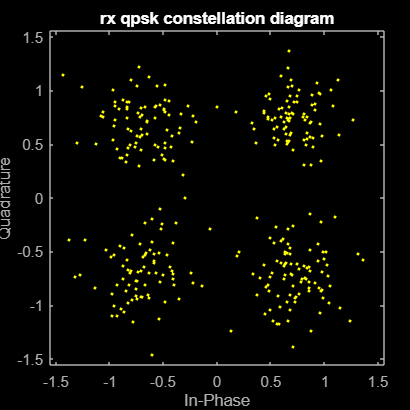

rxSymbols = rxSymbolsWithCP(cpLen+1:end, :);%remove cp from top of matrix (cplen +2 because matlab takes from the next sample to the end)
%fft
rxSymbolsFreq = fft(rxSymbols, numSC);% fft to freq domain
%qpsk
rxQPSKSymbols = rxSymbolsFreq(:);
demodulatedBits = zeros(length(rxQPSKSymbols)*2, 1);

if counter==nLoops
    figure;
    scatterplot(rxQPSKSymbols);
    title('rx qpsk constellation diagram');
end


% Demodulate QPSK symbols to bits
for k = 1:length(rxQPSKSymbols)
    [~, idx] = min(abs(rxQPSKSymbols(k) - symbolMap));
    demodulatedBits(2*k-1:2*k) = de2bi(idx-1, 2, 'left-msb');
end

errors=sum(demodulatedBits'~=messageBits(1:dataLength)')

errors = 65

errors = 55

errors = 33

errors = 23

errors = 11

errors = 9

errors = 4

errors = 1

nbiot_ber(counter)=errors/dataLength

nbiot_ber = 0.0967

nbiot_ber =     0.0967    0.0818


nbiot_ber =     0.0967    0.0818    0.0491


nbiot_ber =     0.0967    0.0818    0.0491    0.0342


nbiot_ber =     0.0967    0.0818    0.0491    0.0342    0.0164


nbiot_ber =     0.0967    0.0818    0.0491    0.0342    0.0164    0.0134


nbiot_ber =     0.0967    0.0818    0.0491    0.0342    0.0164    0.0134    0.0060


nbiot_ber =     0.0967    0.0818    0.0491    0.0342    0.0164    0.0134    0.0060    0.0015



symbolRate=samplingRate/SPS

symbolRate = 15000

symbolRate = 15000

symbolRate = 15000

symbolRate = 15000

symbolRate = 15000

symbolRate = 15000

symbolRate = 15000

symbolRate = 15000

bitRate =  2*12*symbolRate

bitRate = 360000

bitRate = 360000

bitRate = 360000

bitRate = 360000

bitRate = 360000

bitRate = 360000

bitRate = 360000

bitRate = 360000

EbN0_sim(counter)=SNR*samplingRate/bitRate

EbN0_sim = 6.5000

EbN0_sim =     6.5000    7.0000


EbN0_sim =     6.5000    7.0000    7.5000


EbN0_sim =     6.5000    7.0000    7.5000    8.0000


EbN0_sim =     6.5000    7.0000    7.5000    8.0000    8.5000


EbN0_sim =     6.5000    7.0000    7.5000    8.0000    8.5000    9.0000


EbN0_sim =     6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000


EbN0_sim =     6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000



SNR_linear = 10^(SNR / 10);
Eb_N0(counter) = (SNR_linear * samplingRate) / bitRate

Eb_N0 = 9.9763

Eb_N0 =     9.9763   12.5594


Eb_N0 =     9.9763   12.5594   15.8114


Eb_N0 =     9.9763   12.5594   15.8114   19.9054


Eb_N0 =     9.9763   12.5594   15.8114   19.9054   25.0594


Eb_N0 =     9.9763   12.5594   15.8114   19.9054   25.0594   31.5479


Eb_N0 =     9.9763   12.5594   15.8114   19.9054   25.0594   31.5479   39.7164


Eb_N0 =     9.9763   12.5594   15.8114   19.9054   25.0594   31.5479   39.7164   50.0000


end

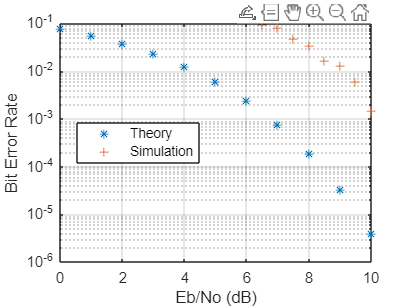

%ber
%https://nl.mathworks.com/help/releases/R2023a/comm/ug/analytical-expressions-used-in-berawgn-function-and-bit-error-rate-analysis-app.html
EbN0=(0:10);
ber=berawgn(EbN0,"psk",4,"nondiff");
figure
semilogy(EbN0',ber,'*')
hold on
semilogy(EbN0_sim',nbiot_ber,'+')
legend({'Theory','Simulation'},'Location','best')
xlabel('Eb/No (dB)')
ylabel('Bit Error Rate')
grid on